# 参数

clear,clc
%全交换面积计算参数
Lr = 4.1;%辐射管长度
Ws = 3.6;%钢板宽
Wfur = 4.6;%炉宽
epsilon_r = 0.5;%黑度
rho_r = 0.5;%反射率
epsilon_w = 0.85;
rho_w = 0.15;
epsilon_s = 0.75;
rho_s = 0.25;
%序号 直径 段长 h1 h2 辐射管间隔数组 功率数组
cellZoneInfo = {1,0.3,8.7,0.65,0.91,[2700 600 600 600 600 600 1200 600 1200],[115 150 115 150 115 150 115 150 115/2];
         2,0.3,7.2,0.65,0.91,[600 600 600 600 600 600 600 600 600 600 600 600],[115/2 150 115 150 115 150 115 150 115 150 115 150 95/2];
         3,0.28,7.2,0.66,0.92,[600 600 600 600 600 600 1200 600 1200 600],[95/2 120 95 120 95 120 95 120 95 120 95/2];
         4,0.28,7.2,0.66,0.92,[600 2400 600 600 1200 600 600 600],[95/2 120 95 120 95 120 95 120 95/2];
         5,0.28,7.2,0.66,0.92,[600 1200 600 1200 600 1200 600 1200],[95/2 120 95 120 95 120 95 120 95/2];
         6,0.28,7.2,0.66,0.92,[1200 1200 1200 1200 1200 1200],[95/2 120 95 120 95 120 95/2];
         7,0.28,6.6,0.66,0.92,[1200 2400 1800 1200],[95/2 120 95 120 95/2];
         8,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[95/2 80 55 80 55/2];
         9,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         10,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         11,0.208,9.3,0.696,0.956,[1800 1800 1800 1800 2100],[55/2 80 55 120 95];}

cellZoneInfo = 11×7 cell 数组
    {[ 1]}    {[0.3000]}    {[8.7000]}    {[0.6500]}    {[0.9100]}    {[         2700 600 600 600 600 600 1200 600 1200]}    {[                    115 150 115 150 115 150 115 150 57.5000]}
    {[ 2]}    {[0.3000]}    {[7.2000]}    {[0.6500]}    {[0.9100]}    {[600 600 600 600 600 600 600 600 600 600 600 600]}    {[57.5000 150 115 150 115 150 115 150 115 150 115 150 47.5000]}
    {[ 3]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[      600 600 600 600 600 600 1200 600 1200 600]}    {[            47.5000 120 95 120 95 120 95 120 95 120 47.5000]}
    {[ 4]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[              600 2400 600 600 1200 600 600 600]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 5]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[            600 1200 600 1200 600 1200 600 1200]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 6]}    {[0.2800]}   


%三元法计算参数
%初(xia)始(gei)化区域温度场
Tw_init = [700 720 740 760 780 800 820 840 860 870 870] + 273.15 +300;
Ts_1_init = [150 250 420 555 666 777 820 835 850 870 870] + 273.15;
% Ts_1_init = [350 550 620 755 866 977 1020 1035 1050 1070 1070] + 273.15;

Lfur = 82.2;%炉长,m
ths = 50/1000;%板厚,m
Time_heat = 80 * 60;%加热时间,s
Vs = Lfur / Time_heat;%物料速度
Thw = 0.3;%炉墙厚度
lambda_w = 0.138*250/300+0.15*50/300;%炉墙导热系数
hw = 15;%炉墙自然对流换热系数
Temp_out = 30+273.15;%环境温度,k
density_s = 7860;
sigma = 5.67*10^(-8);%斯忒藩-玻尔兹曼常数
N = 10;%层数
timeStep = 1000;%时间步长节点数
Ts_2 = 0;%初始化，进循环用

# 全交换面积calc  1.1ver

SR = zeros(1,length(cellZoneInfo));
SW = zeros(1,length(cellZoneInfo));
WR = zeros(1,length(cellZoneInfo));


for i = 1:length(cellZoneInfo)

    %计算
    S = cellZoneInfo{i,6}./1000;%辐射管间隔数组
    d = cellZoneInfo{i,2};%辐射管直径
    L = cellZoneInfo{i,3};%段长
    h1 = cellZoneInfo{i,4};%见函数
    h2 = cellZoneInfo{i,5};
    kr = Lr/Wfur;%辐射管长度系数
    ks = Ws/Wfur;%钢板宽度系数

    xrp = zeros(1,length(S));
    for j = 1:length(S)
        if S(j) == 2.7 || S(j) == 2.1
            xrp(j) = (d/2)/S(j)*atan(S(j)/(d/2));
        else
            xrp(j) = S(j)/(pi*d)*(1+d/S(j)*acos(d/S(j))-(1-(d/S(j))^2)^(1/2));
        end
    end
    %加权辐射管对假想面角系数
    Xrp = 0;
    for j = 1:length(xrp)
        Xrp = Xrp+S(j)/L*xrp(j);
    end
    %角系数

    Xp1w2 = phi_p1_w2(Wfur,L,h1) + phi_p2_w1(Wfur,L,h1);
    Xp2s = phi_p2_s(Wfur,L,h2);
    Xp2w1 = phi_p2_w1(Wfur,L,h2);
    
    % 论文中修正的角系数
    % Xrs = Xrp * 1/kr * Xp2s * ks;%计算Xrs
    Xrw = Xrp * 1/kr *Xp1w2 + Xrp * 1/kr *Xp2w1;
    Xrr = 1 - 2 * Xrp;%计算Xrr
    % Xrr = 1 - Xrw - Xrs;%完整性计算Xrr
    Xrs = 1 - Xrw - Xrr;%完整性计算Xrs
    
    %不修正的角系数
    % Xrs = Xrp * Xp2s ;
    % Xrw = Xrp *Xp1w2 + Xrp *Xp2w1;
    % Xrr = 1 - 2 * Xrp;

    Fs = L*Ws;
    Fw = L*Wfur+L*h1*2+L*h2*2;
    Fr = pi*d*length(S)*Lr;

    Xss= 0;
    Xsr = Xrs * Fr/Fs;
    Xsw = 1 - Xsr - Xss;
    Xwr = Xrw * Fr/Fw;
    Xws = Xsw * Fs/Fw;
    Xww = 1 - Xwr - Xws;
    %直接交换面积
    rr = Fr * Xrr;
    rw = Fr * Xrw;
    rs = Fr * Xrs;
    wr = Fw * Xwr;
    ww = Fw * Xww;
    ws = Fw * Xws;
    sr = Fs * Xsr;
    sw = Fs * Xsw;
    ss = Fs * Xss;

    %全交换面积

    SR(i) = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr);
    SW(i) = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww);
    WR(i) = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww);
    
end
% SR = SR + 100;
% SW = SW + 100;
% WR = WR + 100;

RS = SR

RS =     4.5115    7.0134    5.6168    4.5826    4.5835    3.5048    2.3996    1.7822    1.7822    1.7822    1.9301


WS = SW

WS =    17.3465   10.4000   11.9667   13.1323   13.1309   14.3494   14.0650   16.3139   16.3139   16.3139   21.5975


RW = WR

RW =     8.7697   12.8364   10.3866    8.5359    8.5374    6.5778    4.4526    3.3940    3.3940    3.3940    3.8616


SR

SR =     4.5115    7.0134    5.6168    4.5826    4.5835    3.5048    2.3996    1.7822    1.7822    1.7822    1.9301


SW

SW =    17.3465   10.4000   11.9667   13.1323   13.1309   14.3494   14.0650   16.3139   16.3139   16.3139   21.5975


WR

WR =     8.7697   12.8364   10.3866    8.5359    8.5374    6.5778    4.4526    3.3940    3.3940    3.3940    3.8616


# 三元法calc   1.1ver

**Todo:**已确定炉围初始温度场对出炉钢温有较大影响，黑度增加对炉围钢温无影响疑似与无炉围一维差分计算有关，现停止更改无炉围一维差分修正温度的版本，上传分支并增加炉围一维计算。

%初始化
Tw_zone = zeros(1,length(cellZoneInfo));
Tr_zone = zeros(1,length(cellZoneInfo));
Ts_zone = zeros(1,length(cellZoneInfo));

phi_r = zeros(1,length(cellZoneInfo));

Temp_inlet = zeros(N+1,length(cellZoneInfo));
Temp_inlet(:,1) = 30 + 273.15;
Temp_total = zeros(length(cellZoneInfo),timeStep*length(cellZoneInfo));

for i = 1:length(cellZoneInfo)

    phi_r(i) = sum(cellZoneInfo{i,7})*1000;%W
    Tw = Tw_init(i);
    Ts_1 = Ts_1_init(i);%段内物料表面初始温度
    L = cellZoneInfo{i,3};%段长
    Time_zone = L / Vs;%段内时间

    % RW(i)
    % RS(i)
    % WS(i)

    %能量平衡解Tr
    while(abs((Ts_2 - Ts_1)/Ts_1)>=0.0001)
        Ts_1 = Ts_2;
        syms Tr;
        f1 = sigma*RW(i)*(Tr^4 - Tw^4) + sigma*RS(i)*(Tr^4 - Ts_1^4) == phi_r(i);
        Tr = solve(f1,Tr);
        Tr = vpa(Tr);
        Tr= Tr(imag(Tr) == 0 & real(Tr) > 0);

    %能量平衡解Tw   
        syms Tw;
        f2 = sigma*SW(i)*(Ts_1^4 - Tw^4) + sigma*RW(i)*(Tr^4 - Tw^4) == Fw*(Tw - Temp_out)/(1/hw+Thw/lambda_w);
        Tw = solve(f2,Tw);
        Tw = vpa(Tw);
        Tw= Tw(imag(Tw) == 0 & real(Tw) > 0);

    %求表面热流    
        qcon = -(sigma*RS(i)*(Ts_1^4 - Tr^4) + sigma*WS(i)*(Ts_1^4 - Tw^4))/Fs;%钢坯表面热流密度

    %差分求物料温度   
        T = Temp_inlet(:,i);
        delta_t = Time_zone / timeStep;%时间步长
        delta_x = ths/(2*N);%空间步长
        Temp_zone = zeros(length(cellZoneInfo),timeStep);
        for j = 1:timeStep
            T = TDMA(qcon,N,density_s,delta_t,delta_x,T);
            Temp_zone(:,j) = T;
        end
    
        Ts_2 = sum(Temp_zone(1,:))/timeStep;%热流反算物料表面温度
    
        % if abs((Ts_2 - Ts_1)/Ts_1)<=0.001
        %     break;
        % end
    end
    
    % sprintf('%.3e', phi_r(i)/sigma)
    % sprintf('%.3e', RW(i)*Tw^4)
    % sprintf('%.3e', RS(i)*Ts_2^4)

    Temp_inlet(:,i+1) = T
    Tw_zone(i) = Tw ;%K
    Tr_zone(i) = Tr ;%K
    Ts_zone(i) = Ts_2 ;%K
    Temp_total(:,1+(i-1)*timeStep:i*timeStep) = Temp_zone;%K

end

Temp_inlet =   303.1500  474.9165         0         0         0         0         0         0         0         0         0
  303.1500  473.0581         0         0         0         0         0         0         0         0         0
  303.1500  471.4001         0         0         0         0         0         0         0         0         0
  303.1500  469.9409         0         0         0         0         0         0         0         0         0
  303.1500  468.6791         0         0         0         0         0         0         0         0         0
  303.1500  467.6135         0         0         0         0         0         0         0         0         0
  303.1500  466.7430         0         0         0         0         0         0         0         0         0
  303.1500  466.0668         0         0         0         0         0         0         0         0         0
  303.1500  465.5843         0         0         0         0         0         0         0         

Temp_inlet =   303.1500  474.9165  658.5950         0         0         0         0         0         0         0         0
  303.1500  473.0581  655.4845         0         0         0         0         0         0         0         0
  303.1500  471.4001  652.7149         0         0         0         0         0         0         0         0
  303.1500  469.9409  650.2818         0         0         0         0         0         0         0         0
  303.1500  468.6791  648.1811         0         0         0         0         0         0         0         0
  303.1500  467.6135  646.4092         0         0         0         0         0         0         0         0
  303.1500  466.7430  644.9634         0         0         0         0         0         0         0         0
  303.1500  466.0668  643.8412         0         0         0         0         0         0         0         0
  303.1500  465.5843  643.0410         0         0         0         0         0         0         

Temp_inlet =   303.1500  474.9165  658.5950  766.0460         0         0         0         0         0         0         0
  303.1500  473.0581  655.4845  763.6810         0         0         0         0         0         0         0
  303.1500  471.4001  652.7149  761.5788         0         0         0         0         0         0         0
  303.1500  469.9409  650.2818  759.7347         0         0         0         0         0         0         0
  303.1500  468.6791  648.1811  758.1444         0         0         0         0         0         0         0
  303.1500  467.6135  646.4092  756.8046         0         0         0         0         0         0         0
  303.1500  466.7430  644.9634  755.7123         0         0         0         0         0         0         0
  303.1500  466.0668  643.8412  754.8652         0         0         0         0         0         0         0
  303.1500  465.5843  643.0410  754.2614         0         0         0         0         0         

Temp_inlet =   303.1500  474.9165  658.5950  766.0460  844.3724         0         0         0         0         0         0
  303.1500  473.0581  655.4845  763.6810  842.3165         0         0         0         0         0         0
  303.1500  471.4001  652.7149  761.5788  840.4830         0         0         0         0         0         0
  303.1500  469.9409  650.2818  759.7347  838.8697         0         0         0         0         0         0
  303.1500  468.6791  648.1811  758.1444  837.4750         0         0         0         0         0         0
  303.1500  467.6135  646.4092  756.8046  836.2974         0         0         0         0         0         0
  303.1500  466.7430  644.9634  755.7123  835.3355         0         0         0         0         0         0
  303.1500  466.0668  643.8412  754.8652  834.5885         0         0         0         0         0         0
  303.1500  465.5843  643.0410  754.2614  834.0554         0         0         0         0         

Temp_inlet =   303.1500  474.9165  658.5950  766.0460  844.3724  921.3946         0         0         0         0         0
  303.1500  473.0581  655.4845  763.6810  842.3165  919.2280         0         0         0         0         0
  303.1500  471.4001  652.7149  761.5788  840.4830  917.2887         0         0         0         0         0
  303.1500  469.9409  650.2818  759.7347  838.8697  915.5770         0         0         0         0         0
  303.1500  468.6791  648.1811  758.1444  837.4750  914.0930         0         0         0         0         0
  303.1500  467.6135  646.4092  756.8046  836.2974  912.8371         0         0         0         0         0
  303.1500  466.7430  644.9634  755.7123  835.3355  911.8092         0         0         0         0         0
  303.1500  466.0668  643.8412  754.8652  834.5885  911.0096         0         0         0         0         0
  303.1500  465.5843  643.0410  754.2614  834.0554  910.4384         0         0         0         

Temp_inlet =   303.1500  474.9165  658.5950  766.0460  844.3724  921.3946  980.8189         0         0         0         0
  303.1500  473.0581  655.4845  763.6810  842.3165  919.2280  979.0957         0         0         0         0
  303.1500  471.4001  652.7149  761.5788  840.4830  917.2887  977.5533         0         0         0         0
  303.1500  469.9409  650.2818  759.7347  838.8697  915.5770  976.1920         0         0         0         0
  303.1500  468.6791  648.1811  758.1444  837.4750  914.0930  975.0120         0         0         0         0
  303.1500  467.6135  646.4092  756.8046  836.2974  912.8371  974.0133         0         0         0         0
  303.1500  466.7430  644.9634  755.7123  835.3355  911.8092  973.1960         0         0         0         0
  303.1500  466.0668  643.8412  754.8652  834.5885  911.0096  972.5602         0         0         0         0
  303.1500  465.5843  643.0410  754.2614  834.0554  910.4384  972.1061         0         0         

Temp_inlet = 1.0e+03 *

    0.3031    0.4749    0.6586    0.7660    0.8444    0.9214    0.9808    1.0147         0         0         0
    0.3031    0.4731    0.6555    0.7637    0.8423    0.9192    0.9791    1.0136         0         0         0
    0.3031    0.4714    0.6527    0.7616    0.8405    0.9173    0.9776    1.0126         0         0         0
    0.3031    0.4699    0.6503    0.7597    0.8389    0.9156    0.9762    1.0117         0         0         0
    0.3031    0.4687    0.6482    0.7581    0.8375    0.9141    0.9750    1.0110         0         0         0
    0.3031    0.4676    0.6464    0.7568    0.8363    0.9128    0.9740    1.0103         0         0         0
    0.3031    0.4667    0.6450    0.7557    0.8353    0.9118    0.9732    1.0098         0         0         0
    0.3031    0.4661    0.6438    0.7549    0.8346    0.9110    0.9726    1.0094         0         0         0
    0.3031    0.4656    0.6430    0.7543    0.8341    0.9104    0.9721    1.0091        

Temp_inlet = 1.0e+03 *

    0.3031    0.4749    0.6586    0.7660    0.8444    0.9214    0.9808    1.0147    1.0373         0         0
    0.3031    0.4731    0.6555    0.7637    0.8423    0.9192    0.9791    1.0136    1.0367         0         0
    0.3031    0.4714    0.6527    0.7616    0.8405    0.9173    0.9776    1.0126    1.0361         0         0
    0.3031    0.4699    0.6503    0.7597    0.8389    0.9156    0.9762    1.0117    1.0355         0         0
    0.3031    0.4687    0.6482    0.7581    0.8375    0.9141    0.9750    1.0110    1.0351         0         0
    0.3031    0.4676    0.6464    0.7568    0.8363    0.9128    0.9740    1.0103    1.0347         0         0
    0.3031    0.4667    0.6450    0.7557    0.8353    0.9118    0.9732    1.0098    1.0343         0         0
    0.3031    0.4661    0.6438    0.7549    0.8346    0.9110    0.9726    1.0094    1.0341         0         0
    0.3031    0.4656    0.6430    0.7543    0.8341    0.9104    0.9721    1.0091    1.03

Temp_inlet = 1.0e+03 *

    0.3031    0.4749    0.6586    0.7660    0.8444    0.9214    0.9808    1.0147    1.0373    1.0594         0
    0.3031    0.4731    0.6555    0.7637    0.8423    0.9192    0.9791    1.0136    1.0367    1.0588         0
    0.3031    0.4714    0.6527    0.7616    0.8405    0.9173    0.9776    1.0126    1.0361    1.0583         0
    0.3031    0.4699    0.6503    0.7597    0.8389    0.9156    0.9762    1.0117    1.0355    1.0578         0
    0.3031    0.4687    0.6482    0.7581    0.8375    0.9141    0.9750    1.0110    1.0351    1.0573         0
    0.3031    0.4676    0.6464    0.7568    0.8363    0.9128    0.9740    1.0103    1.0347    1.0570         0
    0.3031    0.4667    0.6450    0.7557    0.8353    0.9118    0.9732    1.0098    1.0343    1.0567         0
    0.3031    0.4661    0.6438    0.7549    0.8346    0.9110    0.9726    1.0094    1.0341    1.0565         0
    0.3031    0.4656    0.6430    0.7543    0.8341    0.9104    0.9721    1.0091    1.03

Temp_inlet = 1.0e+03 *

    0.3031    0.4749    0.6586    0.7660    0.8444    0.9214    0.9808    1.0147    1.0373    1.0594    1.0817
    0.3031    0.4731    0.6555    0.7637    0.8423    0.9192    0.9791    1.0136    1.0367    1.0588    1.0810
    0.3031    0.4714    0.6527    0.7616    0.8405    0.9173    0.9776    1.0126    1.0361    1.0583    1.0805
    0.3031    0.4699    0.6503    0.7597    0.8389    0.9156    0.9762    1.0117    1.0355    1.0578    1.0800
    0.3031    0.4687    0.6482    0.7581    0.8375    0.9141    0.9750    1.0110    1.0351    1.0573    1.0796
    0.3031    0.4676    0.6464    0.7568    0.8363    0.9128    0.9740    1.0103    1.0347    1.0570    1.0792
    0.3031    0.4667    0.6450    0.7557    0.8353    0.9118    0.9732    1.0098    1.0343    1.0567    1.0790
    0.3031    0.4661    0.6438    0.7549    0.8346    0.9110    0.9726    1.0094    1.0341    1.0565    1.0787
    0.3031    0.4656    0.6430    0.7543    0.8341    0.9104    0.9721    1.0091    1.03

Temp_inlet = 1.0e+03 *

    0.3031    0.4749    0.6586    0.7660    0.8444    0.9214    0.9808    1.0147    1.0373    1.0594    1.0817    1.1236
    0.3031    0.4731    0.6555    0.7637    0.8423    0.9192    0.9791    1.0136    1.0367    1.0588    1.0810    1.1228
    0.3031    0.4714    0.6527    0.7616    0.8405    0.9173    0.9776    1.0126    1.0361    1.0583    1.0805    1.1220
    0.3031    0.4699    0.6503    0.7597    0.8389    0.9156    0.9762    1.0117    1.0355    1.0578    1.0800    1.1213
    0.3031    0.4687    0.6482    0.7581    0.8375    0.9141    0.9750    1.0110    1.0351    1.0573    1.0796    1.1207
    0.3031    0.4676    0.6464    0.7568    0.8363    0.9128    0.9740    1.0103    1.0347    1.0570    1.0792    1.1202
    0.3031    0.4667    0.6450    0.7557    0.8353    0.9118    0.9732    1.0098    1.0343    1.0567    1.0790    1.1198
    0.3031    0.4661    0.6438    0.7549    0.8346    0.9110    0.9726    1.0094    1.0341    1.0565    1.0787    1.1195
    0.30

Tw_zone - 273.15%各段温度

ans =   623.7174  790.9901  731.4876  728.6639  772.2982  788.5196  793.4622  788.9165  806.9983  827.2954  860.8317


Tr_zone - 273.15

ans = 1.0e+03 *

    0.9039    0.9544    0.9065    0.9099    0.9373    0.9624    0.9671    0.9456    0.9492    0.9634    1.0142


Ts_zone - 273.15

ans =   119.5483  296.6477  438.4848  531.6840  609.9581  677.2600  723.5916  752.1484  775.1527  797.4054  829.9814


Temp_zone(1,timeStep) - 273.15 %物料出炉温度

ans = 850.4853

Temp_total = Temp_total -273.15%钢温温度场

Temp_total =    33.4012   32.5946   33.9471   33.9609   34.6398   34.8835   35.3228   35.6142   35.9567   36.2441   36.5396   36.8110   37.0787   37.3334   37.5819   37.8219   38.0560   38.2837   38.5063   38.7240   38.9373   39.1467   39.3525   39.5550   39.7546   39.9515   40.1459   40.3382   40.5284   40.7168   40.9035   41.0887   41.2726   41.4552   41.6367   41.8171   41.9966   42.1752   42.3531   42.5302   42.7067   42.8826   43.0580   43.2328   43.4073   43.5813   43.7549   43.9283   44.1013   44.2740
   31.3013   31.5730   32.2560   32.6020   33.0628   33.4040   33.7688   34.0855   34.4001   34.6912   34.9743   35.2436   35.5045   35.7558   35.9998   36.2365   36.4672   36.6921   36.9120   37.1272   37.3383   37.5456   37.7496   37.9504   38.1484   38.3438   38.5369   38.7279   38.9170   39.1044   39.2901   39.4745   39.6575   39.8393   40.0200   40.1998   40.3786   40.5567   40.7339   40.9105   41.0865   41.2620   41.4369   41.6113   41.7854   41.9590   42.1323   42.3053   42.






% 获取所有处理区间的长度，并将其转换为 x 坐标区间长度
process_vector = [cellZoneInfo{:,3}] * 1000;

% 初始化 x 坐标和 y 坐标
x_total = [];
y1_total = [];
y11_total = [];

% 累积和计算 x 坐标
x_start = 0;
for i = 1:length(cellZoneInfo)
    % 计算当前区间的 x 坐标
    x_end = x_start + process_vector(i);
    x = linspace(x_start, x_end, timeStep);
    x_total = [x_total, x];
    
    % 创建当前区间的矩阵 
    matrix = Temp_total(:, 1 + (i-1) * timeStep : i * timeStep);
    
    % 提取第一行和最后一行
    y1 = matrix(1, :);
    y11 = matrix(11, :);
    
    % 累积 y 坐标
    y1_total = [y1_total, y1];
    y11_total = [y11_total, y11];
    
    % 更新 x 起点
    x_start = x_end;
end

# 绘图      1.0ver

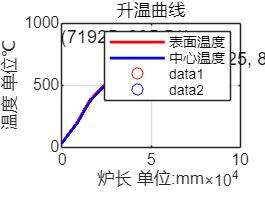

%物料升温曲线
% 绘制折线图
figure;
plot(x_total, y1_total, 'r-', 'LineWidth', 1.5); % 第一行用红色绘制
hold on;
plot(x_total, y11_total, 'b-', 'LineWidth', 1.5); % 最后一行用蓝色绘制

% 添加图例和标签
legend('表面温度', '中心温度');
xlabel('炉长 单位:mm');
ylabel('温度 单位℃');
title('升温曲线');

% 显示网格
grid on;

% 查找 x = 71925 对应的 y 值
x_target = 71925;
[~, idx] = min(abs(x_total - x_target)); % 找到最接近 x_target 的索引
y1_target = y1_total(idx);
y11_target = y11_total(idx);

% 在图中标注 x = 71925 时对应的 y 值
plot(x_target, y1_target, 'ro'); % 在表面温度曲线上的标注
text(x_target, y1_target, sprintf('(%d, %.2f)', x_target, y1_target), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

plot(x_target, y11_target, 'bo'); % 在中心温度曲线上的标注
text(x_target, y11_target, sprintf('(%d, %.2f)', x_target, y11_target), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');

hold off;

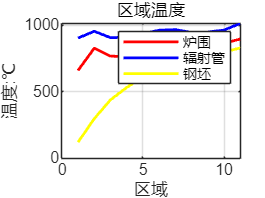



%三元各区域升温曲线
x = linspace(1,11,11);
yTw = Tw_zone - 237.15;
yTr = Tr_zone - 273.15;
yTs = Ts_zone - 273.15;

% 绘制折线图
figure;
plot(x, yTw, 'r-', 'LineWidth', 1.5);
hold on;
plot(x, yTr, 'b-', 'LineWidth', 1.5); 
hold on;
plot(x, yTs, 'y-', 'LineWidth', 1.5); 


% 添加图例和标签
legend('炉围', '辐射管', '钢坯');
xlabel('区域');
ylabel('温度:℃');
title('区域温度');

% 显示网格
grid on;
hold off;

**函数**

%计算空间角系数
%x为炉宽，m;h为炉高，m;y为炉段长度，m;h1为辐射管上端距炉墙高度，m;h2为辐射管下端距假象面p高度，m
function phi = phi_p1_w2(x, y, h1)
    X = x / h1;
    Y = y / h1;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_s(x, y, h2)
    X = x / h2;
    Y = y / h2;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_w1(x, y, h2)
    H = h2 / y;
    W = x / y;
    
    term1 = W * atan(1 / W) + H * atan(1 / H);
    term2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    term3 = (1 + W^2) * (1 + H^2) / (1 + W^2 + H^2) * (W^2 * (1 + W^2 + H^2) / ((1 + W^2) * (W^2 + H^2)))^(W^2);
    term4 = (H^2 * (1 + H^2 + W^2) / ((1 + H^2) * (H^2 + W^2)))^(H^2);
    phi = (2 / (pi * W)) * (term1 - term2 + 1/4*log(term3 * term4));
end

function phi = phi_p2_w11(x, y, h2)
    % 定义H和W
    H = h2 / y;
    W = x / y;
    
    % 计算第一部分
    part1 = W * atan(1 / W) + H * atan(1 / H);
    
    % 计算第二部分
    part2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    
    % 计算第三部分中的内部分数
    term1_numerator = (1 + W^2) * (1 + H^2);
    term1_denominator = 1 + W^2 + H^2;
    term1 = term1_numerator / term1_denominator;
    
    term2_numerator = W^2 * (1 + W^2 + H^2);
    term2_denominator = (1 + W^2) * (W^2 + H^2);
    term2 = term2_numerator / term2_denominator;
    term2 = term2^(W^2);
    
    term3_numerator = H^2 * (1 + H^2 + W^2);
    term3_denominator = (1 + H^2) * (H^2 + W^2);
    term3 = term3_numerator / term3_denominator;
    term3 = term3^(H^2);
    
    % 计算第三部分
    part3 = (1/4) * log(term1 * term2 * term3);
    
    % 计算最终结果
    phi = (2 / (pi * W)) * (part1 - part2 + part3);
    
end

%全交换面积计算

function SR = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr)
    % 计算 SR
    numerator = -Fr * epsilon_r * Fs * epsilon_s * (-Fw * rho_w * Xwr * Xws + Fs * Xsr * (-1 + rho_w * Xww));
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SR = numerator / denominator;
end

function SW = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww)
    % 计算 SW
    numerator = Fw * epsilon_w * Fs * epsilon_s * (Fs * rho_r * Xsr * Xwr + Fr * (1 - rho_r * Xrr) * Xws);
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SW = numerator / denominator;
end

function WR = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww)
    % 计算 WR
    numerator = Fr * epsilon_r * Fw * epsilon_w * (Fs * rho_s * Xsr * Xsw + Fw * Xwr);
    denominator = -Fr * (-1 + rho_r * Xrr) * (Fs * rho_s * rho_w * Xsw^2 + Fw * (-1 + rho_w * Xww)) ...
                  + Fw * rho_r * (Fw * rho_w * Xwr^2 + Fs * rho_s * Xsr * (Xsr + 2 * rho_w * Xsw * Xwr - rho_w * Xsr * Xww));
    WR = -numerator / denominator;
end

%TDMA求解全隐式差分
%热流 离散层数 密度 时间步长 空间步长 上一时刻温度场
function T = TDMA(Qcon,N,density,delta_t,delta_x,T)
    %初始化
    Cp_point = zeros(1,N+1);
    Lambda_point = zeros(1,N+1);

    for i = 1 : N+1
        [Cp_point(i) , Lambda_point(i)] = calPhysicalParameters(1 , T(i));
    end
    Cp_layer = computeAdjacentAverages(Cp_point);
    Lambda_Layer = computeAdjacentHarmonicAverages(Lambda_point);
    Fo = Lambda_Layer./(density.*Cp_layer)*delta_t/(delta_x^2);
    T(1) = T(1) + 2*Fo(1)*(T(2) - T(1) + Qcon*delta_x/Lambda_Layer(1));
    T(N+1) = T(N+1) + 2*Fo(N)*(T(N) - T(N+1));
    a = -Fo(2:N-1);
    b = 1 + computeAdjacentSums(Fo);
    c = -Fo(2:N-1);
    d = T(2:N);
    d(1) = d(1) + Fo(1) * T(1);
    d(N-1) = d(N-1) + Fo(N) * T(N+1);
    
    x = tridiagonal_vector(a,b,c,d);%三对角矩阵算法
    % 检查向量长度以确保可以替换
    if length(T) < 2 || length(x) ~= length(T) - 2
        error('向量 T 和 x 的长度不匹配，无法进行替换');
    end
    % 替换 T 的第 2 到第 N 个元素为 x 的第 1 到第 N-1 个元素
    T(2:end-1) = x;
end


%计算相邻两元素的算术平均值
function avgArray = computeAdjacentAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    avgArray = zeros(1, n-1);

    % 计算相邻元素的算术平均值
    for i = 1:n-1
        avgArray(i) = (inputArray(i) + inputArray(i+1)) / 2;
    end
end


%计算相邻两元素的调和平均值
function harmonicAvgArray = computeAdjacentHarmonicAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的调和平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    harmonicAvgArray = zeros(1, n-1);

    % 计算相邻元素的调和平均值
    for i = 1:n-1
        harmonicAvgArray(i) = 2 / (1/inputArray(i) + 1/inputArray(i+1));
    end
end

%计算两相邻元素的加和
function sumArray = computeAdjacentSums(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的和
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    sumArray = zeros(1, n-1);

    % 计算相邻元素的和
    for i = 1:n-1
        sumArray(i) = inputArray(i) + inputArray(i+1);
    end
end


